# Cruise Control: Frequency Domain method

## System Parameter

m = 1000;
b = 50;
r = 10; % reference speed
s = tf('s');
G = 1/(m*s + b);

## Performance specification

- Rise time < 5 sec

- Overshoot < 10%

- Steady-state error < 2%

## Propotional designer

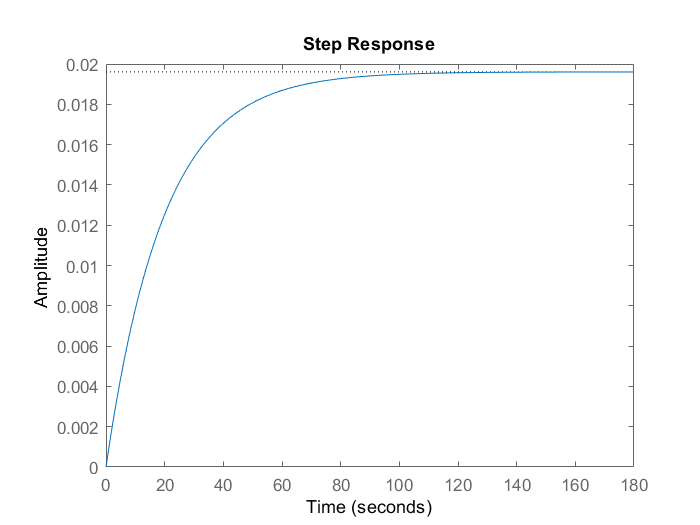

K = 1;
sys = feedback(1*G, 1);
step(sys);

Too much steady state error, the steady state $\;\mathrm{ss}=\frac{1}{1+M\left(0\right)}$, where M is from the open-loop bode magnitude plot

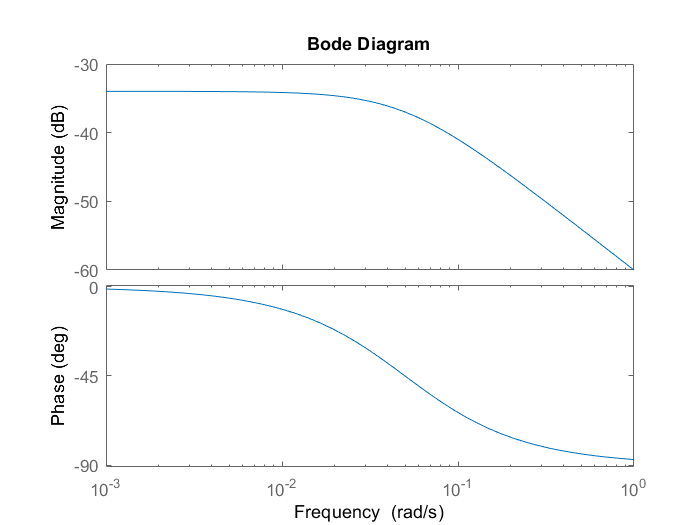

bode(K*G);

For this system, the low frequency gain is -34dB = 0.02; therefore, the steady-state error should be 98%. If we want a 2% steady state error, then M(0) should be equal to larger than 49 which is 33.8dB. From -34db to 33.8db means we need K of 2500

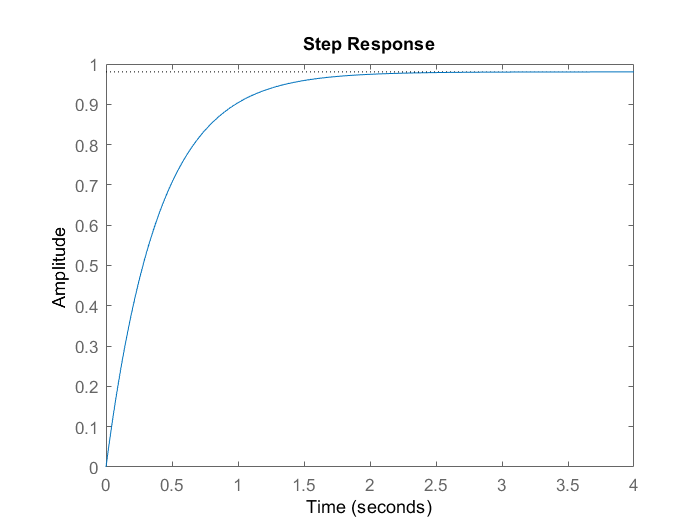

K1 = 2500;
sys1 = feedback(K1*G, 1);
step(sys1);

## Lag controller

The lag controller can increase the gain at low frequency but won't affect bandwidth, and we can use it in our case.

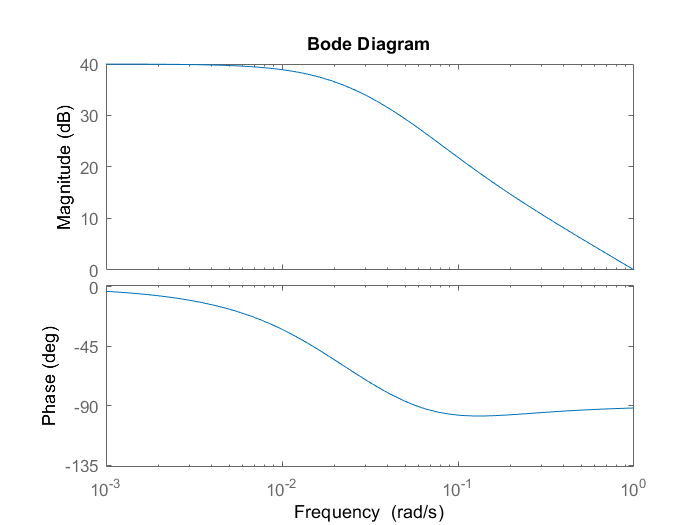

Kp = 1000;
zo = 0.1;
po = 0.02;

C_lag = (s+zo)/(s+po);
bode(Kp*C_lag*G);

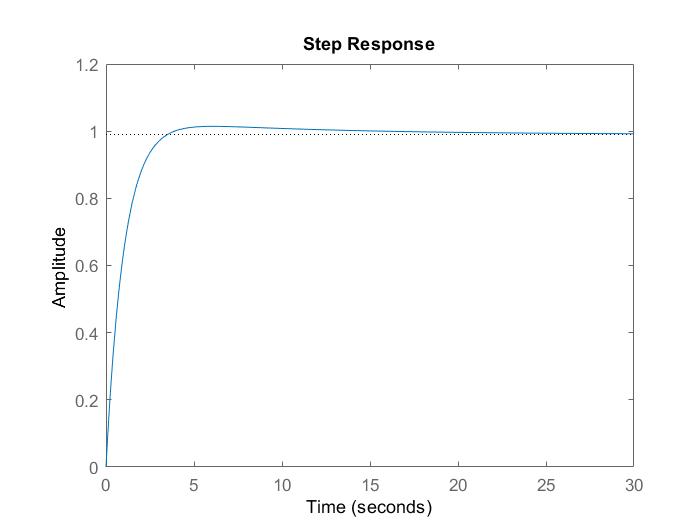


sys_cl = feedback(Kp*C_lag*G,1);
step(sys_cl);